%clear all;
close all;
clc;

% Target capacitance of MMC bank
mmcBankCapTarget = 0.0444e-6; % F
% Capacitance of MMC capacitor
mmcCap = 0.1e-6;   % F

% Number of parallel branches
Np = 3;

% Number of series capacitor(s) per branch
Ns = 1:1:10

Ns =      1     2     3     4     5     6     7     8     9    10



mmcBankCap = (mmcCap./Ns)*Np

mmcBankCap = 1.0e-06 *

    0.3000    0.1500    0.1000    0.0750    0.0600    0.0500    0.0429    0.0375    0.0333    0.0300


mmcBankCapError = abs(mmcBankCap-mmcBankCapTarget)/mmcBankCapTarget

mmcBankCapError =     5.7568    2.3784    1.2523    0.6892    0.3514    0.1261    0.0347    0.1554    0.2492    0.3243


[minBankCapError, idx] = min(mmcBankCapError);

fprintf("MMC Bank Capacitance: %0.4f uF, target: %0.4f uF (error: %0.2f %%) \n",mmcBankCap(idx)*1e6,mmcBankCapTarget*1e6, minBankCapError * 100);

MMC Bank Capacitance: 0.0429 uF, target: 0.0444 uF (error: 3.47 %) 


fprintf("%d caps in series in %d parallel branches (%d total caps) \n",Ns(idx),Np, Np*Ns(idx));

7 caps in series in 3 parallel branches (21 total caps) 


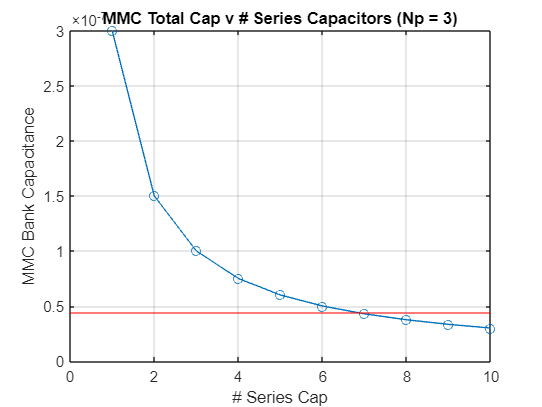

figure();
plot(Ns, mmcBankCap,'-o');
hold on;
yline(mmcBankCapTarget,'r');
grid on;
xlabel('# Series Cap');
ylabel('MMC Bank Capacitance');
title(sprintf("MMC Total Cap v # Series Capacitors (Np = %d)",Np));